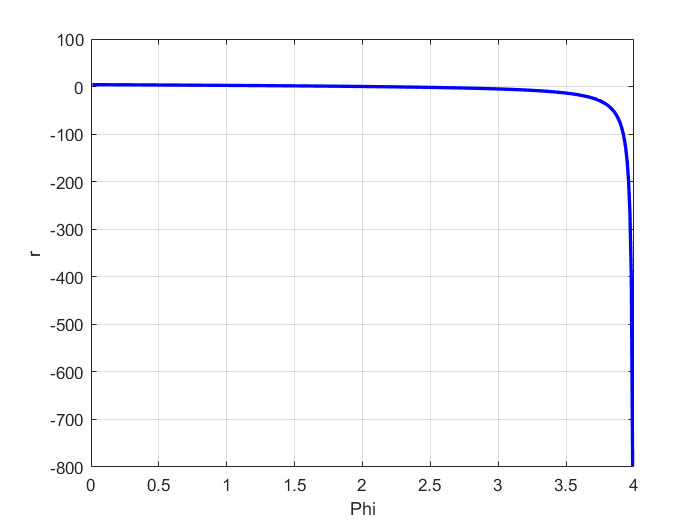

%% This MATLAB® code is for plotting the stability indices
% Re-type the following code in MATLAB® new script and run the file to get theoutput.
clc;
clear;
phi=0.01:0.01:4;
alrad = pi.*sqrt(phi);
al = radtodeg (alrad);
% Compression
r = (alrad.*((sind(al))-(alrad.*cosd(al))))./((2.*(1-cosd(al)))-(alrad.*(sind(al)))); % rotation function
c = (alrad-sind(al))./(sind(al)-(alrad.*cosd(al))); % rotation function
t = 1-((pi*pi*phi)./(2.*r.*(1+c))); % Translation function
outcomp = [phi' r' c' t'];
% for zero
outzero = [0 4.0 0.5 1.0];
% Tension
phit =10:-0.1:0.1;
alrad = pi.*sqrt(phit);
al = radtodeg (alrad);
rt = (alrad.*((alrad.*cosh(alrad))-sinh(alrad)))./((2.*(1-cosh(alrad)))+(alrad.*sinh(alrad)));
ct = (alrad-sinh(alrad))./(sinh(alrad)-(alrad.*cosh(alrad)));
tt = 1-((pi*pi*(-phit))./(2.*rt.*(1+ct)));
outten = [-phit' rt' ct' tt'];
% Stability chart
out = [outten; outzero; outcomp];
filename='StabilityChart111.xlsx';
sheet=1;
xlswrite(filename,out,sheet);
phi = outcomp(:,1);
r = outcomp(:,2);
c = outcomp(:,3);
t = outcomp(:,4);

figure;
plot (phi,r,'b','linewidth',2)
xlabel('Phi');
ylabel('r');
grid on;

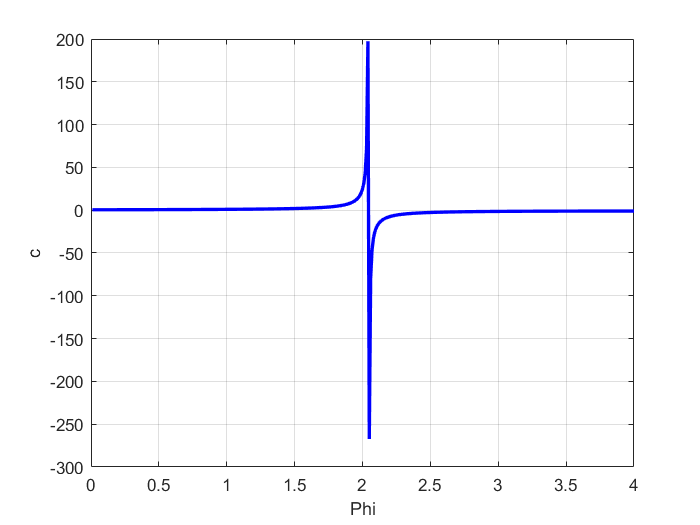

figure;
plot (phi,c,'b','linewidth',2)
xlabel('Phi');
ylabel('c');
grid on;

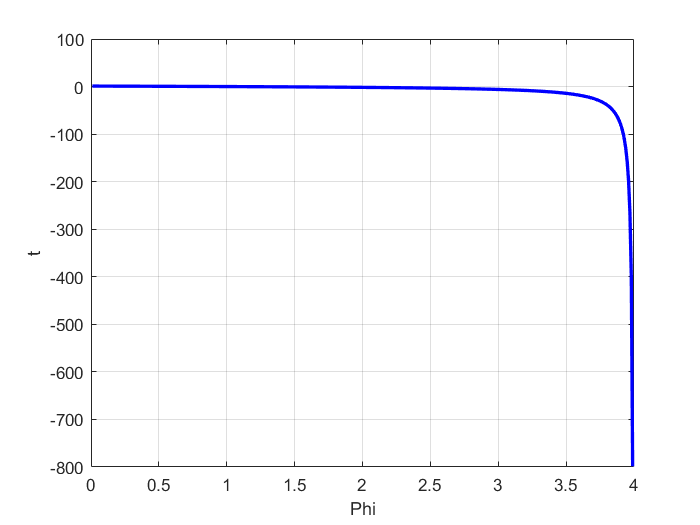

figure;
plot (phi,t, 'b','linewidth',2)
xlabel('Phi');
ylabel('t');
grid on;

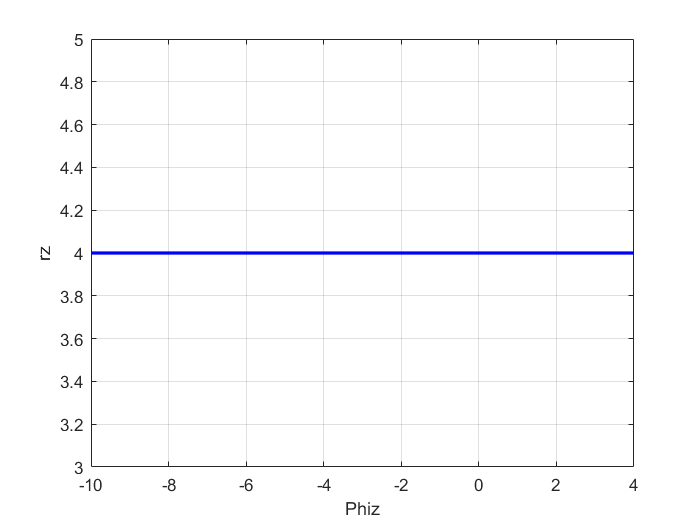

figure;
phiz = out(:,1);
rz(1:501,1:1)=4;
cz(1:501,1:1)=0.5;
tz(1:501,1:1)=1;



figure;
plot (phiz,rz,'b','linewidth',2)
xlabel('Phiz');
ylabel('rz');
grid on;

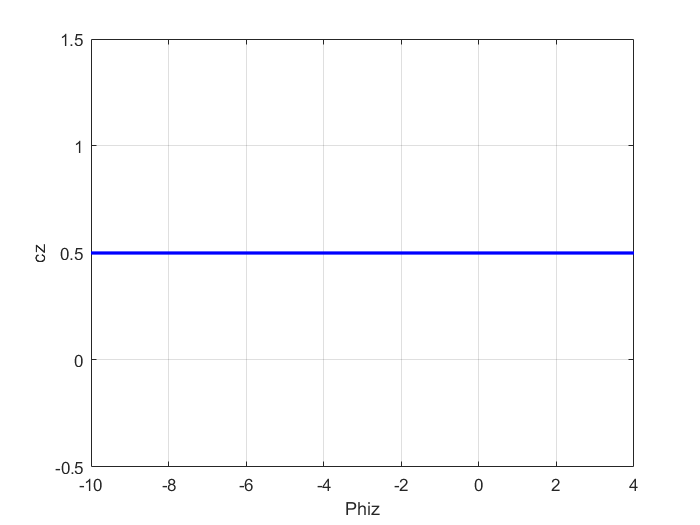

figure;
plot (phiz,cz,'b','linewidth',2)
xlabel('Phiz');
ylabel('cz');
grid on;

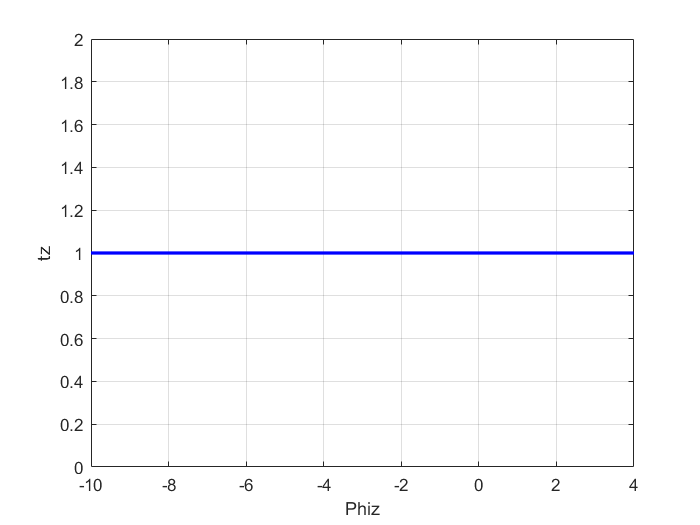

figure;
plot (phiz,tz, 'b','linewidth',2)
xlabel('Phiz');
ylabel('tz');
grid on;

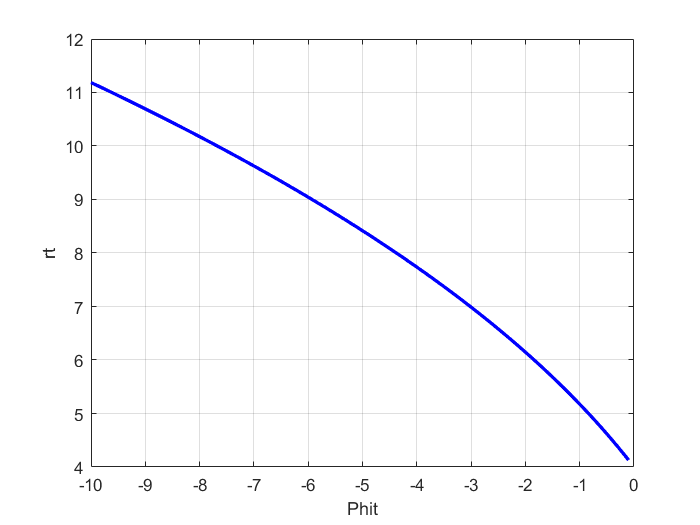

figure;
phit = outten(:,1);
rt = outten(:,2);
ct = outten(:,3);
tt = outten(:,4);

figure;
plot (phit,rt,'b','linewidth',2)
xlabel('Phit');
ylabel('rt');
grid on;

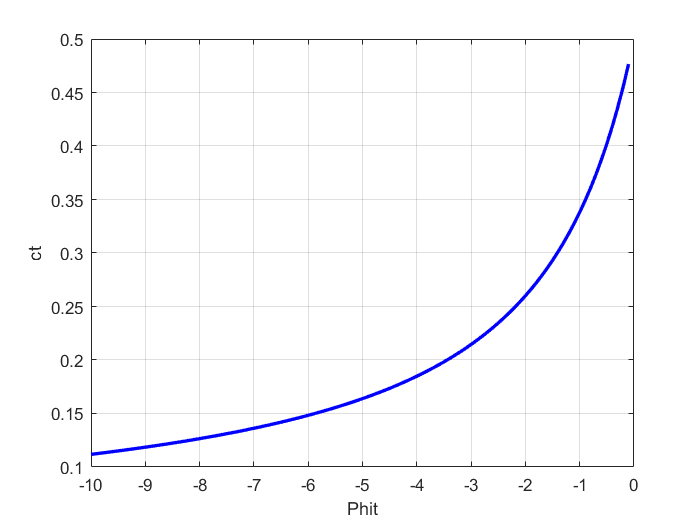

figure;
plot (phit,ct,'b','linewidth',2)
xlabel('Phit');
ylabel('ct');
grid on;

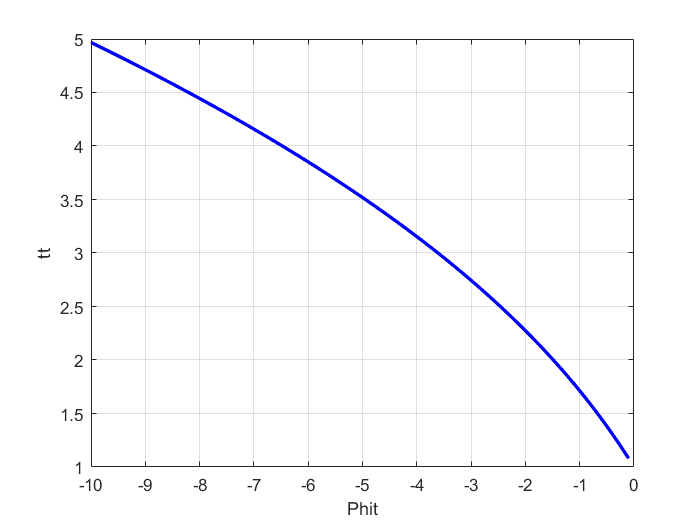

figure;
plot (phit,tt, 'b','linewidth',2)
xlabel('Phit');
ylabel('tt');
grid on;

figure;

